# **Project 5 - Option Pricing with the LSMC Method**  

**1. Consider the following information on the stock of company XYZ: The current stock price is $40, and the volatility of the stock price is 𝜎 = 20% per annum. Assume the prevailing**

**risk-free rate is r = 6% per annum. Use the following method to price the specified option:  **

**(a) Use the LSMC method with N=100,000 paths simulations (50,000 plus 50,000 antithetic variates) and a time step of **


$$\Delta =\frac{1}{\sqrt{N}}$$


**to price an American Put option with strike price of X = $40 and maturity of 0.5-years, 1-year, and 2-years. Use the first k of the Laguerre Polynomials for k = 2, 3, 4. (That is, you will compute 9 prices here). Compare the prices for the 3 cases k = 2, 3, 4 and comment on the choice of k.**

warning('off','all')
warning

All warnings have the state 'off'.


ans = 5.9960

% Laguerre Polynomials
X = 40; sigma = 0.2; r = 0.06; S0 = 40;
T_vec = [0.5,1,2]; N = 100000; k_vec = [2,3,4];

put_am_price = zeros(3,3);
for i =1:3
    k = k_vec(i);fast_put_am = @(t) LSMC_put(X, r, t, N, k, sigma, S0,"laguerre");
    put_am_price(i,:) = arrayfun(@(tTx) fast_put_am(tTx), T_vec);
end
put_am_price

put_am_price =     1.3538    1.3821    1.3946
    1.6989    1.8088    1.8369
    1.7932    2.1376    2.2203


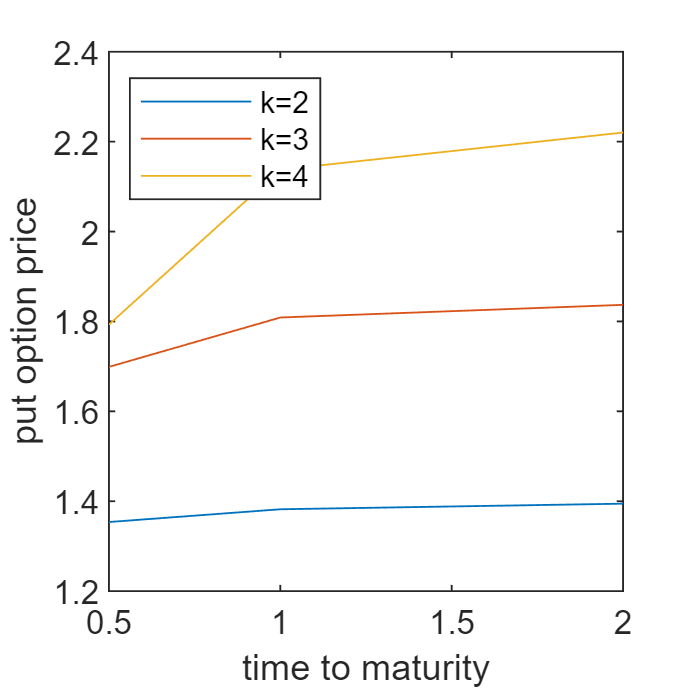

% plot
for i =1:3
    plot(T_vec,put_am_price(i,:))
    hold on
end
hold off
set(gcf,'Position',[250 250 250 250])
legend(["k=2","k=3","k=4"],...
    'Location','northwest','NumColumns',1)
ylabel("put option price")
xlabel("time to maturity")

Comments: Since the American put option should have higher pricing than the European put option. Based on Black-Scholes formula, I know the European put option pricing is 1.68, 2.07 and 2.36 for time to matuiry 0.5, 1 and 2 respectively. So, the correct American put option pricing should be higher than these values. As shown above, only the line of k=4 satisfies this rule. So, I think k=4 is the best choice in this question.

When it comes the reason why Laguerre Polynomials method has such unreasonable pricing if k=2 or 3, the first L(x) term $e^{\frac{-x}{2}}$makes the value is too small, causing the computational accuracy of the computer low. One method to impove it is to rescale by the strike price K. So, the value of $e^{\frac{-x}{2}}$ will be around $e^{\frac{-1}{2}}$, which has high accuracy than somthing like $e^{\frac{-40}{2}}$. The following case is rescaling the value:

% Laguerre Polynomials with rescale
X = 40; sigma = 0.2; r = 0.06; S0 = 40;
T_vec = [0.5,1,2]; N = 100000; k_vec = [2,3,4];

put_am_price = zeros(3,3);
for i =1:3
    % divde the stock price by strike value
    k = k_vec(i);fast_put_am = @(t) X*LSMC_put(1, r, t, N, k, sigma, S0/X,"laguerre");
    put_am_price(i,:) = arrayfun(@(tTx) fast_put_am(tTx), T_vec);
end
put_am_price

put_am_price =     1.7844    2.3031    2.8601
    1.7922    2.3163    2.8702
    1.8006    2.3303    2.8856


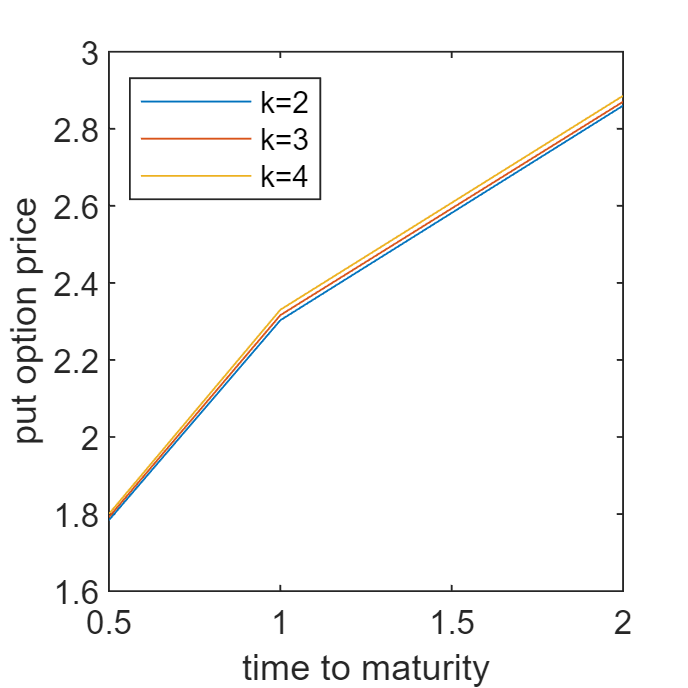

% plot
for i =1:3
    plot(T_vec,put_am_price(i,:))
    hold on
end
hold off
set(gcf,'Position',[250 250 250 250])
legend(["k=2","k=3","k=4"],...
    'Location','northwest','NumColumns',1)
ylabel("put option price")
xlabel("time to maturity")

Now, this plot gives all reasonable pricing.

**(b) Use the LSMC method with N=100,000 paths simulations (50,000 plus 50,000 antithetic variates) and a time step of **


$$\Delta =\frac{1}{\sqrt{N}}$$


**to price an American Put option with strike price of 𝑋 = $40 and maturity of 0.5-years, 1-year, and 2-years. Use the first k of the Hermite Polynomials for k = 2, 3, 4. (That is, you will compute 9 prices here). Compare the prices for the 3 cases k = 2, 3, 4 and comment on the choice of k.**

% Hermite Polynomials
X = 40; sigma = 0.2; r = 0.06; S0 = 40;
T_vec = [0.5,1,2]; N = 100000; k_vec = [2,3,4];

put_am_price_her = zeros(3,3);
for i =1:3
    k = k_vec(i);fast_put_am = @(t) LSMC_put(X, r, t, N, k, sigma, S0,"hermite");
    put_am_price_her(i,:) = arrayfun(@(tTx) fast_put_am(tTx), T_vec);
end
put_am_price_her

put_am_price_her =     1.7702    2.2795    2.8255
    1.7917    2.3104    2.8674
    1.7914    2.3123    2.8943


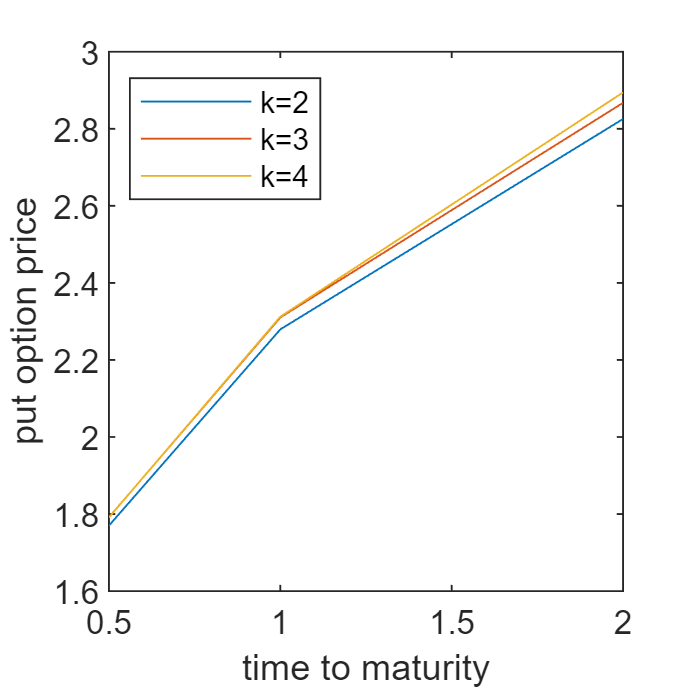

% plot
for i =1:3
    plot(T_vec,put_am_price_her(i,:))
    hold on
end
hold off
set(gcf,'Position',[250 250 250 250])
legend(["k=2","k=3","k=4"],...
    'Location','northwest','NumColumns',1)
ylabel("put option price")
xlabel("time to maturity")

Comments: For Hermite Polynomials method, all three lines' pricing are higher than the Black-Scholes European put opions pricing. Besides, these lines also satisfy the time value (the pricing should be higher if the time to maturity is longer). So, according to these rules, k=2, 3 and 4 all are good choice for Amercian put option pricing. However, since k=4 has higher accuracy (Taylar expansion with higher order terms), I prefer to choose k=4 under the available computational capability.

**(c) Use the LSMC method with N=100,000 paths simulations (50,000 plus 50,000 antithetic variates) and a time step of **


$$\Delta =\frac{1}{\sqrt{N}}$$


**to price an American Put option with strike price of 𝑋 = $40 and maturity of 0.5-years, 1-year, and 2-years. Use the first k of the Simple Polynomials for k = 2, 3, 4. (That is, you will compute 9 prices here). Compare the prices for the 3 cases k = 2, 3, 4 and comment on the choice of k.**

% Simple Polynomials
X = 40; sigma = 0.2; r = 0.06; S0 = 40;
T_vec = [0.5,1,2]; N = 100000; k_vec = [2,3,4];

put_am_price_sim = zeros(3,3);
for i =1:3
    k = k_vec(i);fast_put_am = @(t) LSMC_put(X, r, t, N, k, sigma, S0,"simple");
    put_am_price_sim(i,:) = arrayfun(@(tTx) fast_put_am(tTx), T_vec);
end
put_am_price_sim

put_am_price_sim =     1.7683    2.2743    2.8187
    1.7949    2.3035    2.8790
    1.8000    2.3159    2.8755


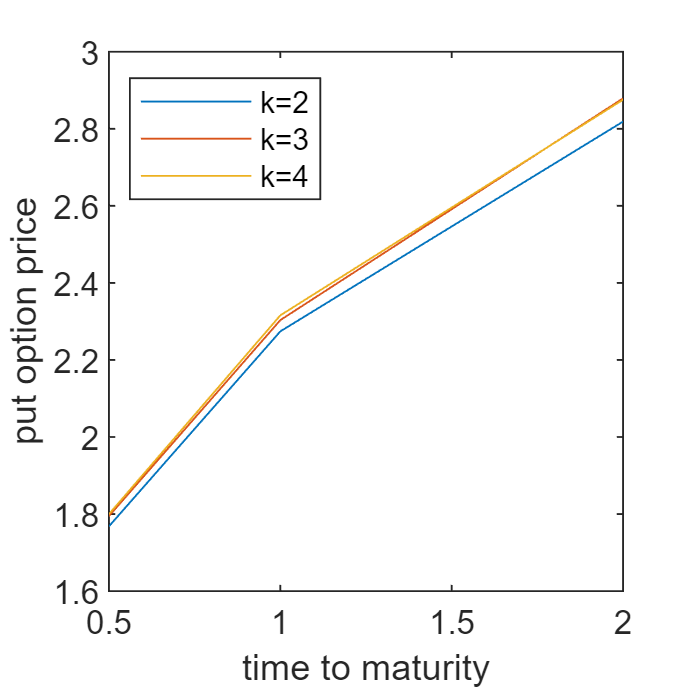

% plot
for i =1:3
    plot(T_vec,put_am_price_sim(i,:))
    hold on
end
hold off
set(gcf,'Position',[250 250 250 250])
legend(["k=2","k=3","k=4"],...
    'Location','northwest','NumColumns',1)
ylabel("put option price")
xlabel("time to maturity")

Comments: For Simple Polynomials method, all three lines' pricing are higher than the Black-Scholes European put opions pricing. Besides, these lines also satisfy the time value (the pricing should be higher if the time to maturity is longer). So, according to these rules, k=2, 3 and 4 all are good choice for Amercian put option pricing. But, generally, k=4 has higher accuracy (Taylar expansion with higher order terms). However, I notice that the line of k=3 has almost the same pricing as the line of k=4. So, considering the efficiency of running time, I prefer to choose k=3 for this question.

**(d) Compare all your findings above and comment.  **

Generally,  k=4 has higher pricing accuracy given the fact that it has higher order terms in Talyor Expansion. To trade-off between the accuracy and compuatioanl capacity, I prefer to choose lower k values to imporve the compuation efficiency if I can keep the accuracy almost unchange. Besides, before these trade-off choice, the pricing should be reasonable, such as higher pricing than European options, option's time value.

Comparing the three methods, Simple Polynomials method is the best considering the conputation efficiency. Laguerre Polynomials method need rescale to improve the efficiency. In Hermite Polynomials method, k=4 with higher order terms has higher pricing than k=3 in all the time to maturity values. Only the Simple Polynomial method need neither rescale nor the 4th order terms -- 3rd order term is enough for the accuracy. So, to the degree, Simple Polynomials method is more efficient in computation.

**functions are as follows:**

function position = find_power(search_area,i)
    if any(search_area(:,i))
        position = find(search_area(:,i));
    else
        position = 0;
    end
end

function x_list = laguerre(x, k)
% laguerre
    if k == 2
        x1 = exp(-x/2);
        x2 = exp(-x/2).*(1-x);
        x_list = [x1',x2'];
    elseif k == 3
        x1 = exp(-x/2);
        x2 = exp(-x/2).*(1-x);
        x3 = exp(-x/2).*(1-2.*x+(x.^2)/2);
        x_list = [x1',x2',x3'];
    elseif k == 4
        x1 = exp(-x/2);
        x2 = exp(-x/2).*(1-x);
        x3 = exp(-x/2).*(1-2.*x+(x.^2)/2);
        x4 = exp(-x/2).*(1-3.*x+(3.*x.^2)/2-(x.^3)/6);
        x_list = [x1',x2',x3',x4'];
    else
        x_list=[];
    end
end

function x_list = hermite(x, k)
% hermite
    if k == 2
        x1 = 1+zeros(size(x));
        x2 = 2*x;
        x_list = [x1',x2'];
    elseif k == 3
        x1 = 1+zeros(size(x));
        x2 = 2*x;
        x3 = 4*x.^2-2;
        x_list = [x1',x2',x3'];
    elseif k == 4
        x1 = 1+zeros(size(x));
        x2 = 2*x;
        x3 = 4*x.^2-2;
        x4 = 8*x.^3-12*x;
        x_list = [x1',x2',x3',x4'];
    else
        x_list=[];
    end
end

function x_list = simple(x, k)
% hermite
    if k == 2
        x1 = 1+zeros(size(x));
        x2 = x;
        x_list = [x1',x2'];
    elseif k == 3
        x1 = 1+zeros(size(x));
        x2 = x;
        x3 = x.^2;
        x_list = [x1',x2',x3'];
    elseif k == 4
        x1 = 1+zeros(size(x));
        x2 = x;
        x3 = x.^2;
        x4 = x.^3;
        x_list = [x1',x2',x3',x4'];
    else
        x_list=[];
    end
end


function [A_X,b_vec,lp_x] = lag_poly(x, k, y, type)
% Laguerre Polynomials
    if type == "laguerre"
        lp_x = laguerre(x,k);
    elseif type == "hermite"
        lp_x = hermite(x,k);
    elseif type == "simple"
        lp_x = simple(x,k);
    else
        lp_x=[];
    end
    A_X = lp_x' * lp_x;
    b_vec = lp_x' * y;
end

function  option_price=LSMC_put(X, r, T, N, k, sigma, S0, type)
    dt = 1/sqrt(N);
    step = ceil(T/dt);
    discount_unit = exp(-r*dt);
    
    rng(7723);
    % stock price
    S_mat = zeros(step+1,N); S_mat(1,:) = S0;
    for i = 2:(step + 1)
        Wt = normrnd(0,sqrt(dt),[1, N/2]);
        % S_mat(i,:) = S_mat(i-1,:)*exp((r-sigma^2/2)*dt+sigma*[Wt, -Wt]);
        S_mat(i,:) = S_mat(i-1,:) + r* S_mat(i-1,:)*dt + sigma*S_mat(i-1,:).*[Wt, -Wt];
    end
    % payoff of put option
    payoff_mat = max(X-S_mat,0);
    
    % index matrix
    index_mat = zeros(step+1, N);
    index_mat(step+1,:) = payoff_mat(step+1,:)>0;
    % expected value
    exp_cont_vec = zeros(size(payoff_mat(step+1,:)));
    
    for i = step:-1:2
        % the valid rows for fitting regression
        idx = payoff_mat(i,:)>0;   
        % find the number of power by the position of i in index matrix
        % row: step; col: simulation sample
        search_area = index_mat(i+1:step+1,idx);
        fast_find = @(sample_idx) find_power(search_area,sample_idx);
        power_num = arrayfun(@(sample_idx) fast_find(sample_idx) , 1:size(search_area,2));
        % use the previous matrix to compute discounted early exercise value
        y = sum(payoff_mat(i+1:step+1,idx).*index_mat(i+1:step+1,idx), 1) .* (discount_unit.^ power_num);
        % regression: L(X)*a_vec = y
        % A(X) = L(X)'*L(X); b_vec = L(X)'*y
        [A_X, b_vec, lp_x] = lag_poly(S_mat(i,idx),k,y',type);
        a_vec = A_X\b_vec;
        % y_hat = L(X)*a_vec
        exp_cont_vec(idx) = lp_x * a_vec;
        % clean the previous index into 0
        clean_idx = payoff_mat(i,:) > exp_cont_vec;
        index_mat(i+1:step+1,clean_idx) = 0;
        % assign new 1s at the current step
        index_mat(i,:) = clean_idx;
        % reset the expected continuous vector
        exp_cont_vec(:) = 0;
    end
    search_area = index_mat(2:step+1,:);
    fast_find = @(sample_idx) find_power(search_area,sample_idx);
    power_num = arrayfun(@(sample_idx) fast_find(sample_idx) , 1:size(search_area,2));
    % use the previous matrix to compute discounted early exercise value
    y = sum(payoff_mat.*index_mat,1) .* (discount_unit.^ power_num);
    % option pricing
    option_price = mean(y,2);
end
